# Capturing How Different Ages Affect the Spread of COVID-19 Under Realistic Conditions

*Authors:* Jaeden Pangaribuan, Jonas Sangster

**Generative AI (genAI) Usage Statement**

No Generative AI was used whilst making this assignment, aside from the many times google AI overview was consulted to fix the many times git decided to get angry.

## 1. Modeling Question

  Our modeling question was how different demographics affect the spread of Covid-19 over time, as we were curious about how disease spread could be modeled with more realistic parameters, like having things like age and human interventions like vaccination will affect the spread of the disease, and if that was something that we could possibly track within our model. Because of this we created a interacting subpopulation SEIRVD model with variable contact rates to expand upon the SIR-reinfectivity model that we were using previously to investigate disease spread, and Covid-19 data to allow us to measure our model in a real world scenario rather than with a simplistic model of disease spread, allowing us to see the effectiveness of our model if it would be used in real life.

Our model is relatively specific, as we are focusing in specifically on Covid-19, and the differences in spread and severity between an older (age > 64) and a younger (age <= 64) subpopulation. We are also including vaccination in our model as an important measure of human intervention in the spread of disease. Our model is relatively rhetorical, as there is not much of a use case for this model at this point in time, as the Covid-19 pandemic occurred 6 years ago -- which is crazy by the way -- and there are many models out there that would more quickly be able to estimate the spread and severity if a new strain of Covid reappeared. Our model does have a couple of key limitations that also apply to this being only for rhetorical purposes of comparing it to a standard SIR- reinfectivity model, with our model not accounting for disease evolution over time, such as new strains of the virus that have different affects on the populous, and other human interventions like masking and social distancing, leading to a model with significant flaws. Our model can also only predict based on past data, and as time has passed, most of the population has gained a resistance to the disease over time, and it is significantly less prevalent, leading to our data not being as timely as we would like it to be.

## 2. Literature Search

We began our process by looking into multiple different possible model designs that we could make in order to much more accurately model how a disease would spread in reality, beginning by looking at different ways that people had already modeled the spread of Covid-19 during the pandemic. We found that variations on a SIR model can be very effective ways to model the disease due to the similarities that the disease has with the flu and the common cold, both of which are very well suited to a SIR model. This was backed up by 42% of models made to measure the spread of Covid-19 across the world were variations on SIR models (Modeling and predicting the spread of Covid-19, 2022, table 16.7). By looking at different ways that countries implemented these SIR models, we decided that we wanted to focus in on having multiple subpopulations of data, which would allow us to have much more accuracy to the disease, as it acts very differently depending on things like the age of someone who is infected with the disease. We also really wanted to be able to measure things like vaccination, and have a period where a person could be exposed to the disease, and not yet be infected, but still pass it on to others. We also wanted to be able to account for deaths due to the disease, allowing us to more accurately maintain the system with people being reinfected after time has passed.

We then researched ways that this type of model has been implemented in the past, and found a paper looking into how different vaccination strategies would affect the spread of disease over a population. This paper had a model with interconnected subpopulations based on age, and also accounted for many of the things that we found most important for our model, leading us to base our design off of the one used in this paper's model for an interconnected subpopulation model that also included vaccination and reinfection, both things that we really cared about adding(Personalized-dose COVID-19 vaccination in a wave of virus Variants of Concern:Trading individual efficacy for societal benefit). The paper was able to give us a lot of insight into the best way to run tests of our model, as they set up multiple different vaccination strategies, and ran simulations with each one, allowing for the measurement of different effects on the population. By combining what we learned with more information about the way that Covid 19 spreads throughout age groups, and the critical insight of being sure to pay attention to things that our model is unable to measure such as new strains of the disease(Modeling Covid transition through age groups) and also that our model does not account for human intervention such as social distancing and masking, we were able to narrow in on our specific interconnected subpopulation SEIRVD model.

## Synthesis Matrix for how different demographics effect the spread of Covid-19

## 3. Natural World

The natural world is represented through our model based on how the disease is interacting differently among different demographics of the population, and how those different populations spread the disease in different ways. This is represented through our model by using multiple interconnected subpopulations, one of older individuals, and one of younger individuals, built to be a combination of the multiple subpopulations represented in "Personalized-dose COVID-19 vaccination in a wave of virus Variants of Concern:Trading individual efficacy for societal benefit" and "Modeling Covid transition through age groups". This allows us to more accurately measure the effects of Covid on the population as it is a disease that is significantly more effective in older individuals, where it has much more extreme effects, yet there are significantly more cases in younger individuals who feel the effects much less than that of older people. Our model also is only focusing on the United States from the period of January 2020 through May 2023, as that is the range of the data that we were able to obtain of Covid cases in people, with enough information about said cases to be applied to our model.

An important difference between our model and the natural world is that within our model we are assuming that the disease does not change and evolve over time, which is a key difference in comparison to real life in which a disease can come up with new strains rapidly that will get around current vaccines and built up immunity. Because we are ignoring diseases causing multiple strains we are losing out on some accuracy in favor of simplicity. In the same way we are also not accounting for human interventions such as masking and social distancing, as human intervention will vary wildly based off of location, perceived severity, and recommendations from authority, and the randomness of humanity would make modeling significantly more complex, and we would lose out on being able to look specificity at different subpopulations as human intervention is often a universal aspect, where either all people in a subgroup are working to prevent disease transfer, or very few people in the subgroup are working to prevent transfer.

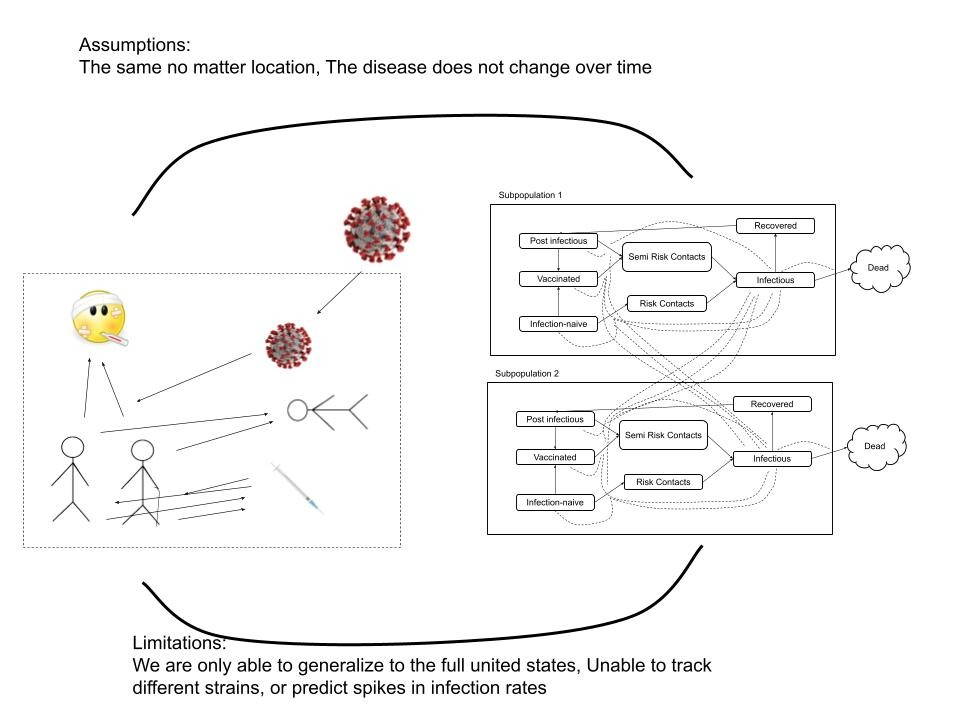

## 4. Model: Representation & Assumptions

*We wanted our model to be much more representative of the natural world, with aspects much closer to how diseases actually transfer in real life, so inside our system we have multiple subpopulations to be able to account for the disease acting differently upon different groups of people. We also wanted to expand the original SIR model to add a exposure period, in which people are affected by the disease, but do not yet have symptoms, allowing for more accurate portrayal of how the disease works in the real world. We also have added in some human interventions through vaccination, which allows us to match some of how humanity will work to prevent a disease.*

*For each subpopulation within our model, we have three different sets of people who are susceptible to be infected, being those who are post infectious, those who are vaccinated, and those who are infection naive, with those who are post infectious, and those who are vaccinated having a lower risk of being reinfected than those who are infection naive. We also have our set of exposed individuals represented through semi risk contacts and risk contacts respectively based off of whether the person who is currently exposed has been infected before, or if they have been vaccinated. Finally we have the group of people who are infected at the moment. All of the values from Figure 1 are then applied into our model, and are then used to calculate the new values used in the next step in the simulation using the equations from Figure 2. Each dashed line within our model is then representative of one of the equations, allowing us to apply specific scalars to each value in order to create the next time stamp of the model. The new values are then applied onto the equations in Figure 3, which represent the ways that the two subpopulations are interconnected, and affect the rate of infection within each other.*

*The main set of assumptions made in our model is that the disease will not grow and evolve over time, allowing us to maintain consistency within our values, and allow for variable contact rates over the course of the simulation, but limits our model's usecases to only one strain of the virus. Another assumption is that there is minimal human intervention into disease control, with only vaccines, and minimal acts such as masking and social distancing. While variable contact rates may somewhat mitigate the issue, it is not enough to account for wildly changing actions of the population.*

***Figure 1.***

% Young people
% Initially set to 0.5 for paper 197000 cases per day, tweaked to 0.35
% after fitting to csv
Pcontact = 0.5;
Pinfectivity_semirisk = 0.0132 % From paper effectiveness;
Pinfectivity_risk = 0.35;

Precovered = 0.9965/7; % 1-fatality rate, divided by 7 since people are infectious for 7 days
Pdeceased = 0.0035/7; % Fatality rate
Pvaccinated = 0.0033; % 1 million vaccinations per day available from paper 
    
% Grabbed from CSV
numPostInfection = 19000000;
numVaccinated = 0;
numNaive = 258141000;
numInfectious = 1155000;
numDeceased = 0;

% Old people
% Initially set to 0.5 for paper 197000 cases per day, tweaked to 0.35
% after fitting to csv
Pcontact = 0.5;
Pinfectivity_semirisk = 0.0414 % From paper effectiveness;
Pinfectivity_risk = 0.35;
Precovered = 0.911/7; % 1 - fatality rate, divided by 7 since people are infectious for 7 days
Pdeceased = 0.089/7; % Fatality rate
Pvaccinated = 0.0033; % 1 million vaccinations per day from paper

%Grabbed from CSV
numPostInfection = 3700000;
numVaccinated = 0;
numNaive = 50378000;
numInfectious = 225000;
numDeceased = 0;


***Figure 2.***

vaccinatedContact = obj.Pcontact * obj.numVaccinated;
postInfectionContact = obj.Pcontact * obj.numPostInfection;

naiveContact = obj.Pcontact * obj.numNaive;

deltaInfectiousVaccine = vaccinatedContact*obj.Pinfectivity_semirisk*infectiousFraction;
deltaInfectiousPostInfection = postInfectionContact*obj.Pinfectivity_semirisk*infectiousFraction;

deltaInfectiousNaive = naiveContact*obj.Pinfectivity_risk*infectiousFraction;

deltaRecovered = obj.Precovered * obj.numInfectious;
deltaDeceased = obj.Pdeceased * obj.numInfectious;

deltaVaccinePostInfection = obj.Pvaccinated*obj.numPostInfection;
deltaVaccineNaive = obj.Pvaccinated*obj.numNaive;

% Must clamp when delta calculated by 3 or more variables;

%   Makes Vaccination only occur after time = 365 instead of
%   10. Though 10 is written, this is variable across every
%   vaccinated person (e.g., we need to keep track of everyone
%   who is vaccinated and when their 10 days has started,
%   which we can do in final draft

if (time < 10) 
    deltaVaccinePostInfection = 0;
    deltaVaccineNaive = 0;
end

obj.numNaive = obj.numNaive - deltaVaccineNaive - deltaInfectiousNaive;
obj.numPostInfection = obj.numPostInfection + deltaRecovered - deltaVaccinePostInfection - deltaInfectiousPostInfection;
obj.numVaccinated = obj.numVaccinated + deltaVaccinePostInfection + deltaVaccineNaive - deltaInfectiousVaccine;
obj.numDeceased = obj.numDeceased + deltaDeceased;
obj.numInfectious = obj.numInfectious + deltaInfectiousPostInfection + deltaInfectiousVaccine + deltaInfectiousNaive - deltaDeceased - deltaRecovered;
obj.newCases = deltaInfectiousNaive + deltaInfectiousVaccine + deltaInfectiousPostInfection;
obj.newDeaths = deltaDeceased;

***Figure 3.***

function simulateAction(obj, time)
% use fraction so numbers don't explode
subpopulation1Infectious = obj.subpopulation1.numInfectious / obj.subpopulation1.getLiving();
subpopulation2Infectious = obj.subpopulation2.numInfectious / obj.subpopulation2.getLiving();

totalInfectious1 = (1-obj.PInfect2Contact1)*subpopulation1Infectious + obj.PInfect2Contact1*subpopulation2Infectious;
totalInfectious2 = (1-obj.PInfect1Contact2)*subpopulation2Infectious + obj.PInfect1Contact2*subpopulation1Infectious;

obj.subpopulation1.simulateAction(time, totalInfectious1);
obj.subpopulation2.simulateAction(time, totalInfectious2);
end


*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

Population counts grabbed from csv

*A: this part of the natural world is important for our question*

*B: but we can't include that directly because of X reason*

*T: so here is the way we represented it / what we assumed to simplify*

## 5. Verification & Validation

We verify the model through three main checks:

1.

assert(abs(total_people - model.getPopulation()) < 1e-3, "Total population changes on day: " + day + ". Calculated: " + model.getPopulation() + ". Expected: " + total_people);

The first check verifies that the initial total amount of people is equivalent to the number of people the model records on that specific day. This confirms the total number of people doesn't change (including deceased people), or else we would have implemented it wrong.

2.

assert(Pcontact + Pvaccinated <= 1, "Flow exceeds stock quantity");

The second check verifies that the flow from post-infection or naive stocks does not exceed its own population. For example, a population of ten infection-naive people cannot flow into seven vaccinated and five infected.

3.

assert(Precovered + Pdeceased <= 1, "Flow exceeds stock quantity");

Similar to the last check, we cannot have the outflow of the infected stock surpass the current quantity in the stock.

We validate the model through one check, ensuring that those who are vaccinated or have already been infected (semirisk) are less infectious than infection-naive people.

assert(Pinfectivity_semirisk <= Pinfectivity_risk, "Vaccinated/post-infected people cannot be more infectious than infection-naive");

## 6. Claims & Limitations

We initially used the model without variable contact rates. However, we decided to add four different contact rates across four periods of time as we know disease infectiousness changes over time (e.g., period 1 has Pinfectivity1, period2 has Pinfectivity2, and so on).

In order to fit the model accurately, we fit it to COVID data from google health:[ https://health.google.com/covid-19/open-data/explorer.](https://health.google.com/covid-19/open-data/explorer.) We explored a time period from January 1, 2021 to August 13, 2021 (32 weeks, 4 blocks of 8 weeks). In each block, we generate a new Pinfectivity based on a parameter sweep and finding the minimum mean squared error (taken from ML strategies).

% array of 4 Pinfectivity values
nBlocks = 4;
blockWeeeks = 8;

schedule = [];
for b = 1:nBlocks
    nw = b*blockWeeks;
    blockErrors = zeros(size(PinfValues));
    %parameter sweep all values
    for i = 1:length(PinfValues)
        modelCases = runModel([schedule, PinfValues(i)], blockWeeks, nw, prevWeekDeaths);
        blockErrors(i) = mean((modelCases - dataCases(1:nw)).^2);
    end
    [~, best] = min(blockErrors);
    % append best Pinf value to schedule
    schedule = [schedule, PinfValues(best)];
end

% final model
[varCases, varDeaths] = runModel(schedule, blockWeeks, nWeeks, prevWeekDeaths);


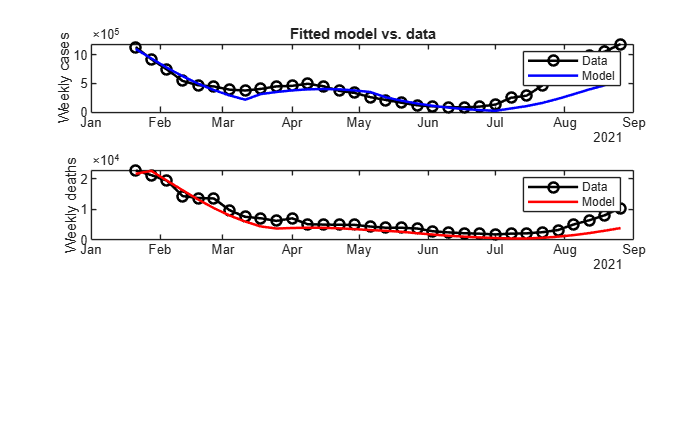

- Final fitted model with four different infectivity values for four different time periods. Each time period lasts 2 months, starting from January.

Then, to find more patterns between different age subpopulations, we used this model to simulate what would happen if we kept the same parameters but normalized the population sizes. Hence, we used our model to simulate half a year (26 weeks) of disease outbreak if the amount of young people was equivalent to the amount of old people. We did not use variable contact rates in this simulation, as the overall trend amongst the curves would be the same, and it would simply change how each time period curves.

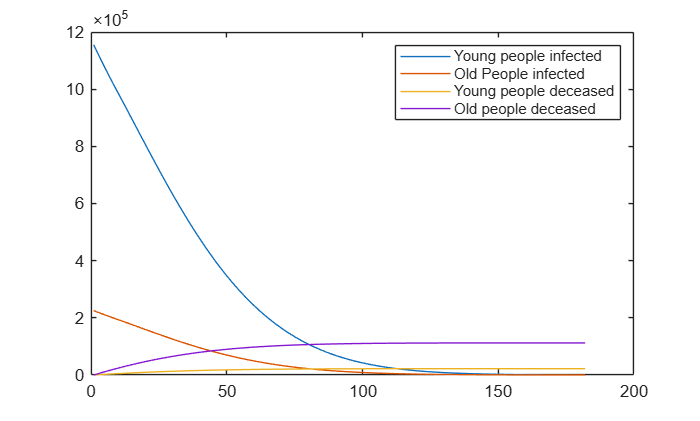

- Initial simulation with varying populations. No variable contact rates used.

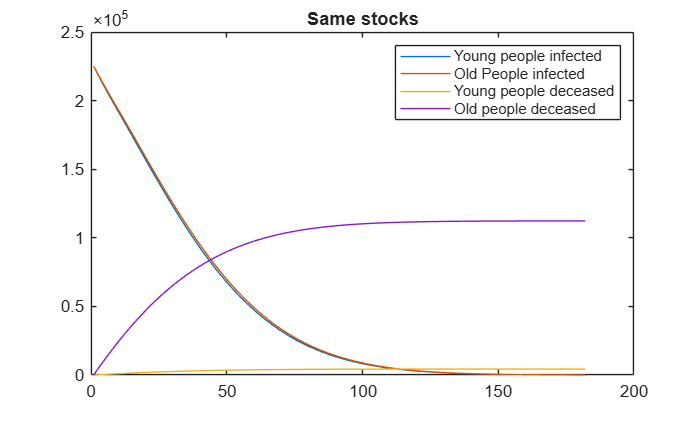

- Simulation where age subpopulations are normalized, with the amount of young people being equal to the amount of old people. No variable contact rates used.

Through these simulations, we found that the curves were nearly identical besides the fatality. This implies they both affect transmission equally, but only some populations are more affected by the disease itself (death rates/severe cases). Our model is validated as it matches real world scenarios where old people have higher fatality rates in comparison to younger people.

Lastly, to confirm that the subpopulations affected transmission equally, we did a parameter sweep between different contact values (A contact rate of 100% means 100% of their contact is with the other population). With this parameter sweep, we found that the 0.5 and 1 contact rates were nearly identical, but the 0 contact rate increased the amount of weekly cases. This indicates that as long as there is some interaction between the age subpopulations, disease outcomes are nearly identical regardless of how much the interaction varies.

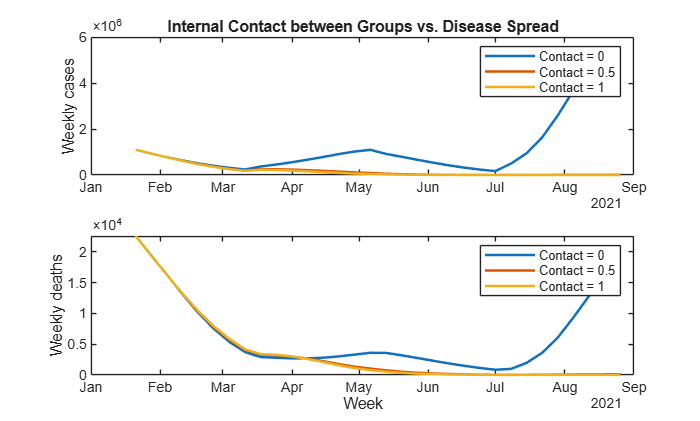

- Parameter sweep of contact rates and resulting deaths/cases from disease. If contact > 0, we find that the curves are nearly identical. Only when there is no contact do we find age subpopulations differently affect the spread of disease.

## 7. Conclusion

We used an interacting subpopulation SEIRVD model with variable contact rates in order to explore how different age subpopulations, the young and old, affected the spread of COVID-19. Once we fit the model to real data, we found that different age subpopulations do not affect transmission differently, regardless of contact rates. This is supported by our simulations finding that varying contact rates between subpopulations do not change disease outcomes as long as there is some interaction (Pcontact > 0). Moreover, we found that normalizing subpopulations to the same quantity of people made disease outcomes nearly identical. Our model found that the only difference amongst these subpopulations is the number of deceased people, mirroring the real world where old people have a greater fatality rate than younger people. 

## 8. Future Work

Some of the ideas that we had for future additions to our model, and other research that could be done to improve the model’s efficacy would be adding in a breakaway function, and differentiating between location from within our data set.

A breakaway function in our data would allow for modeling of new strains of the disease by having the model be able to break away from the current trend, and have an incredibly sharp spike of cases in both susceptible and infected individuals in a short period of time, leading to people having to be re-vaccinated, and allowing for us to model some of the sharp spikes that were experienced by Covid due to new strains such as the Alpha strain and the Omicron strain.

The other main way that we could improve upon our model would be to differentiate between locations within our dataset. As of right now we are lumping together data from all across the united states, and thus losing out on certain differences between demographics that are no longer being represented in the population, such as significantly more antivaxxers in the south leading to lower vaccination rates, and changes in the variable contact rates for those areas due to lower rates of masking.

## References

Hunziker, (2021) Personalized-dose COVID-19 vaccination in a wave of virus Variants of Concern: Trading individual efficacy for societal benefit

Ojojoh, Sarumi, Salako, Gabriel, Taiwo, Johnson, Adegun, Babalola, (2022) Modeling and predicting the spread of COVID-19

Roy, Heath, Wang, Rankrishna, (2022) Modeling COVID-19 transmission between age groups in the United States considering virus mutations, vaccinations, and reinfection

Wikipedia, Compartmental models (epidemiology)